# Rotary Inverted Pendulum System Identification via Constrained Non Linear Optimization and Simulation Error Criterion

The main advantage of employing a simulation error method for system identification is that the procedure is less influenced by fast sampling times and large measurement noise.

## Unconstrained System identification via S.E.M.

addpath("../Model/"); % NL equations
addpath("../optimization/UncOpt/"); % optimization routines
addpath("../optimization/ConsOpt/");
addpath("../Manual_Validation/esp/theta_esp/"); % experimental data
addpath("../Manual_Validation/esp/alpha_esp/");
addpath("../Manual_Validation/esp/theta_d_esp/");
addpath("../Manual_Validation/esp/alpha_d_esp/");
addpath("../Manual_Validation/esp/t_esp/");
addpath("../Manual_Validation/esp/voltage_esp/");
addpath("../")
startUp % load datasheet model parameter values

### Load the Data

Also need to add a procedure to save the results consistently and link the identification esults to the experiment used to perform identification.

Remark: for consistency of use of the optimization toolboxes we will denote in the following the state as $z$ and the decision variables as $x$.

train_exp = 50;

% want row vectors !!!
uin = cell2mat(struct2cell(load('voltage_esp'+ string(train_exp)+'.mat'))); % input voltages signal collected from measurement % place negative sign
Time_vec = cell2mat(struct2cell(load('t_esp'+ string(train_exp)+'.mat'))); % time vector of the measure signals
N = length(Time_vec); % number of samples of the measurement

theta = cell2mat(struct2cell(load('theta_esp'+ string(train_exp)+'.mat')));
alpha = cell2mat(struct2cell(load('alpha_esp'+ string(train_exp)+'.mat')));
theta_dot = cell2mat(struct2cell(load('theta_d_esp'+ string(train_exp)+'.mat')));
alpha_dot=cell2mat(struct2cell(load('alpha_d_esp'+ string(train_exp)+'.mat')));

ymeas = [theta;alpha;theta_dot;alpha_dot];

% check if voltage was measured before or after -1 gain
if uin(1,100) > 0 && theta(1,100) <= 0 || uin(1,100) < 0 && theta(1,100) >= 0
    uin = - cell2mat(struct2cell(load('voltage_esp'+ string(train_exp)+'.mat'))); % consider negative voltages
end

downsample_factor = 1;
Ts = 0.002*downsample_factor; % sampling time of the simulation/data acquisition process
z0 = [ymeas(1,1); ymeas(2,1); 0; 0]; % initial conditions given the modeling conventions

### Weighting matrices for cost function and scaling factor

We should check the orders of magnitude of measured variables in order to avoid numerical issues, it would be great to normalize through a scaling factor.

% Q = eye(2);
Q = eye(4);
Q(1,1) = 1e5;
Q(2,2) = 1e5;

scaling =ones(10,1); 
% scaling = [1e3 1e3 1e3 1e3 1e1 1 1e1 1e1 1e3 1e3]'; % needed only if the parameters to identify are of differnet
% orders of magnitude

### Initialize parameter estimates

we want to estimate the following physical parameters: 


$$B_p ,B_r ,J_{a\;} ,J_p ,l_p ,R_m ,\eta_g ,\eta_m ,k_m ,k_t$$


in a future version we could add the positions of the centers of mass: $l_p$

% x0 = rand([10,1]);
load("x0_BFGS.mat")

### Unconstrained Optimization routine

%% BFGS
% Initialize solver options
% myoptions               =   myoptimset;
% myoptions.Hessmethod  	=	'BFGS';
% myoptions.gradmethod  	=	'CD';
% myoptions.graddx        =	2^-17;
% myoptions.tolgrad    	=	1e-9;
% myoptions.ls_tkmax      =	1;          
% myoptions.ls_beta       =	0.5;
% myoptions.ls_c          =	1e-4;
% myoptions.ls_nitermax   =	100;
% 
% % Run solver
% [xstar,fxstar,niter,exitflag] = myfminunc(@(x)Rot_pend_sim_cost(x,z0,uin,ymeas,th,Ts,Q,scaling),x0,myoptions);

% Results
% [xstar./scaling [B_p;B_r;J_a;J_p;l_p;R_m;eta_g;eta_m;k_m;k_t]]

Here we plot the trajectory of the system for the optimum point and we compare it to the true behaviour of the system in both the training and the validation sets.

% [~,ysim] = Rot_pend_sim_cost(xstar,z0,uin,ymeas,th,Ts,Q,scaling);
% figure,plot(Time_vec,uin);
% figure,plot(Time_vec,ymeas(1,:),Time_vec,ysim(1,:))
% figure,plot(Time_vec,ymeas(2,:),Time_vec,ysim(2,:))
% figure,plot(Time_vec,ymeas(3,:),Time_vec,ysim(3,:))
% figure,plot(Time_vec,ymeas(4,:),Time_vec,ysim(4,:))

## Constrained Optimization

The unconstrained optimization above, despite giving good results leverages negative numbers which are unfeasible for physical quantities such as moment of inertia.

In the following we will try to introduce some linear constraints on parameter values.

### Define the linear inequality constraints matrices 

From physics we impose some limit values for the physical parameters of the system, these limits are here formulated as **linear inequality constraints **of the form $C\;x\ge d$.

C = zeros(20,10);
C(1,1) = 1;
C(2,1) = -1;
C(3,2) = 1;
C(4,2) = -1;
C(5,3) = 1;
C(6,3) = -1;
C(7,4) = 1;
C(8,4) = -1;
C(9,5) = 1;
C(10,5) = -1;
C(11,6) = 1;
C(12,6) = -1;
C(13,7) = 1;
C(14,7) = -1;
C(15,8) = 1;
C(16,8) = -1;
C(17,9) = 1;
C(18,9) = -1;
C(19,10) = 1;
C(20,10) = -1;

d = [1e-4; -3e-3; 1e-4; -3e-3; 1e-4; -2.5e-3; 1e-4; -1.7e-3;1e-4;-0.337;R_m-(R_m*0.12);-(R_m+(R_m*0.12));eta_g-(eta_g*0.1);-(eta_g+(eta_g*0.1));eta_m-(eta_m*0.1);-(eta_m+(eta_m*0.1));k_m-(k_m*0.12);-(k_m+(k_m*0.12));k_t-(k_t*0.12);-(k_t+(k_t*0.12))];
% d = [1e-4; -3e-3; 1e-4; -3e-3; 1e-4; -2.5e-3; 1e-4; -1.7e-3;1e-4;-0.337;1e-4;-(R_m+(R_m*0.12));1e-4;-(eta_g+(eta_g*0.1));1e-4;-(eta_m+(eta_m*0.1));1e-4;-(k_m+(k_m*0.12));1e-4;-(k_t+(k_t*0.12))];

### Optimization routine

% Initialize solver options
myoptions               =   myoptimset;
myoptions.Hessmethod    =   'GN';
% myoptions.Hessmethod  	=	'BFGS';
myoptions.gradmethod  	=	'CD';
myoptions.graddx        =	2^-17;
myoptions.tolgrad    	=	1e-9;
myoptions.ls_tkmax      =	1;          
myoptions.ls_beta       =	0.5;
myoptions.ls_c          =	0.1;
myoptions.ls_nitermax   =	1e2;
myoptions.nitermax      =	1e3;
myoptions.xsequence     =	'on';
myoptions.GN_sigma      =   1e-6; % sufficiently small
myoptions.GN_funF       =   @(x)Rot_pend_sim_err(x,z0,uin,ymeas,th,Ts,Q,scaling);

% Run solver
[xstar,fxstar,niter,exitflag,xsequence] = myfmincon(@(x)Rot_pend_sim_cost(x,z0,uin,ymeas,th,Ts,Q,scaling),x0,[],[],C,d,0,0,myoptions);

Iteration       NormGrad          Cost      Equality     Inequality     Rel. cost         Rel. x     Line-search
        0    2.05068e+08   3.07652e+08   0.00000e+00   -1.91908e+00   1.00000e+00    1.00000e+00               0
        1    3.08922e+10   5.46472e+07   0.00000e+00   -1.10182e-17   8.22443e-01    1.31699e+00               0
        2    3.92513e+09   3.21861e+07   0.00000e+00    0.00000e+00   4.11019e-01    7.57989e-02               0
        3    4.50002e+09   3.13817e+07   0.00000e+00    5.06865e-18   2.49934e-02    1.77605e-02               2
        4    1.88942e+09   2.89187e+07   0.00000e+00    6.26127e-18   7.84840e-02    2.70663e-02               1
        5    1.08752e+10   2.49910e+07   0.00000e+00    0.00000e+00   1.35819e-01    9.90199e-03               0
        6    2.46375e+10   2.28110e+07   0.00000e+00    4.33681e-19   8.72345e-02    3.58664e-02               1
        7    1.24507e+10   1.80083e+07   0.00000e+00   -4.33681e-19   2.10542e-01    3.66498e-02

% Results
[xstar./scaling [B_p;B_r;J_a;J_p;l_p;R_m;eta_g;eta_m;k_m;k_t]]

ans =     0.0004    0.0024
    0.0030    0.0024
    0.0001    0.0020
    0.0007    0.0012
    0.0292    0.1560
    2.4733    2.6000
    0.9900    0.9000
    0.7590    0.6900
    0.0084    0.0077
    0.0068    0.0077


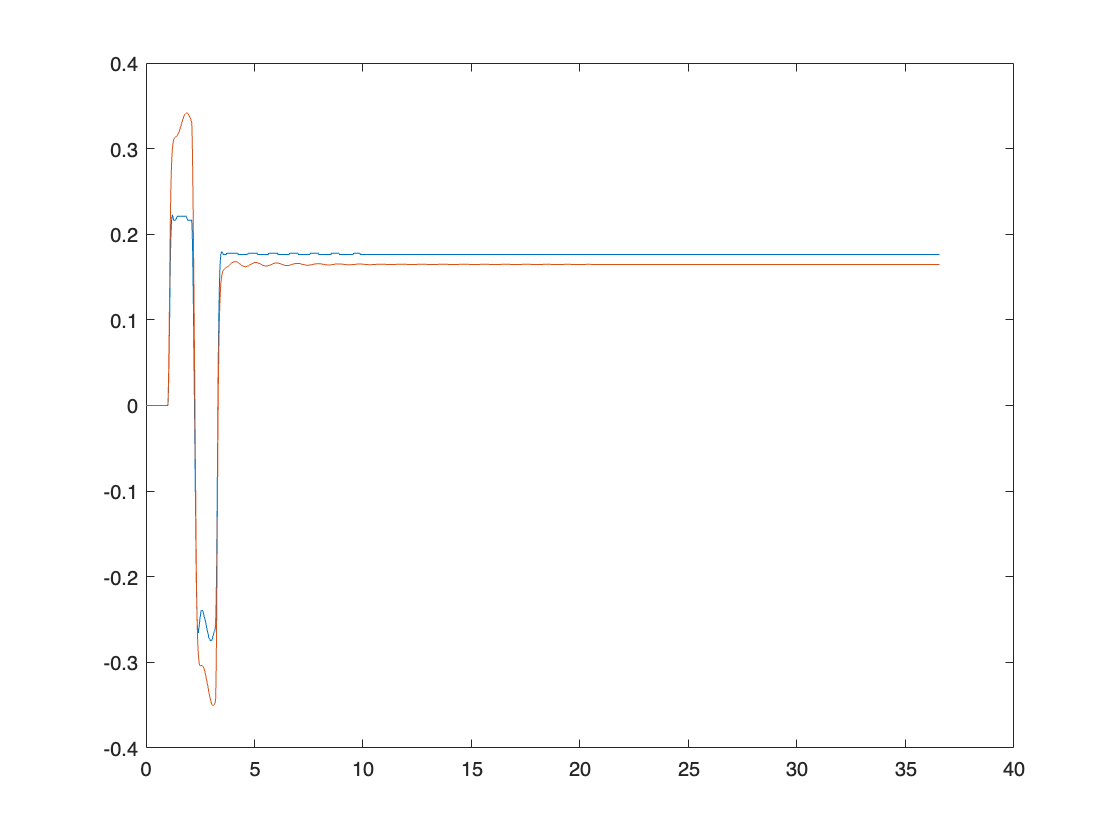

[~,ysim] = Rot_pend_sim_cost(xstar,z0,uin,ymeas,th,Ts,Q,scaling);
figure,plot(Time_vec,ymeas(1,:),Time_vec,ysim(1,:))

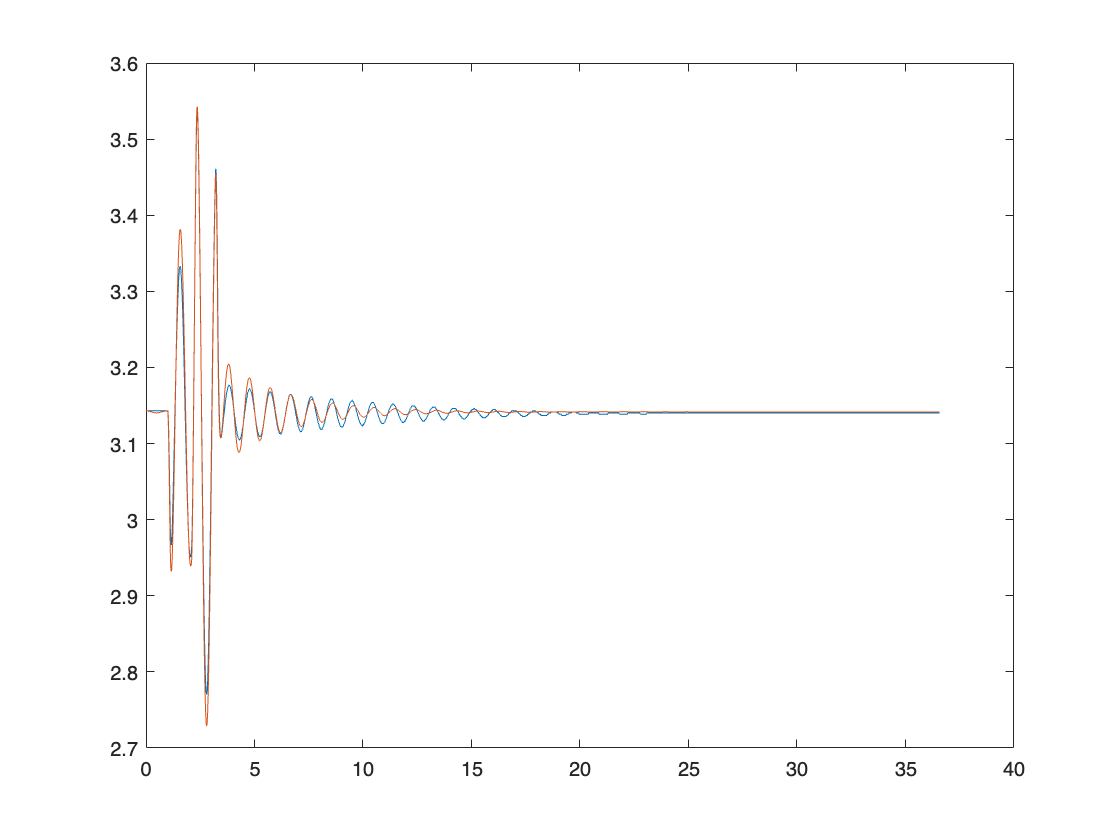

figure,plot(Time_vec,ymeas(2,:),Time_vec,ysim(2,:))

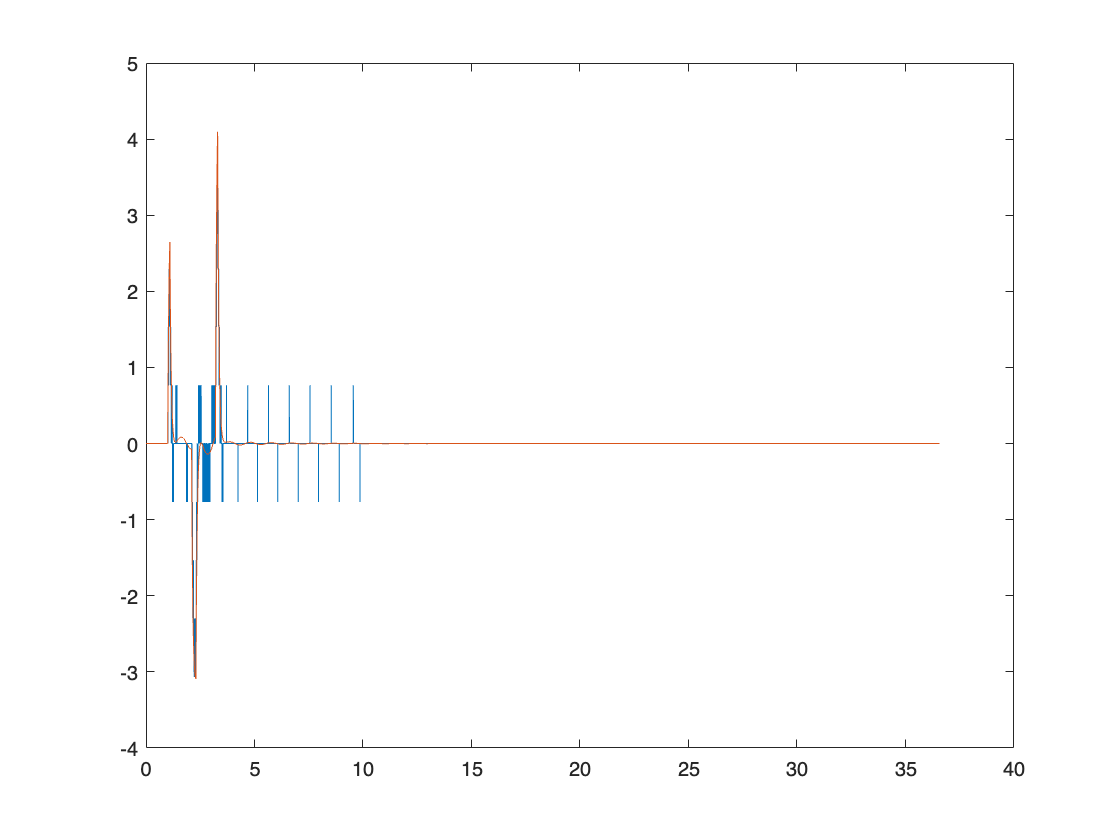

figure,plot(Time_vec,ymeas(3,:),Time_vec,ysim(3,:))

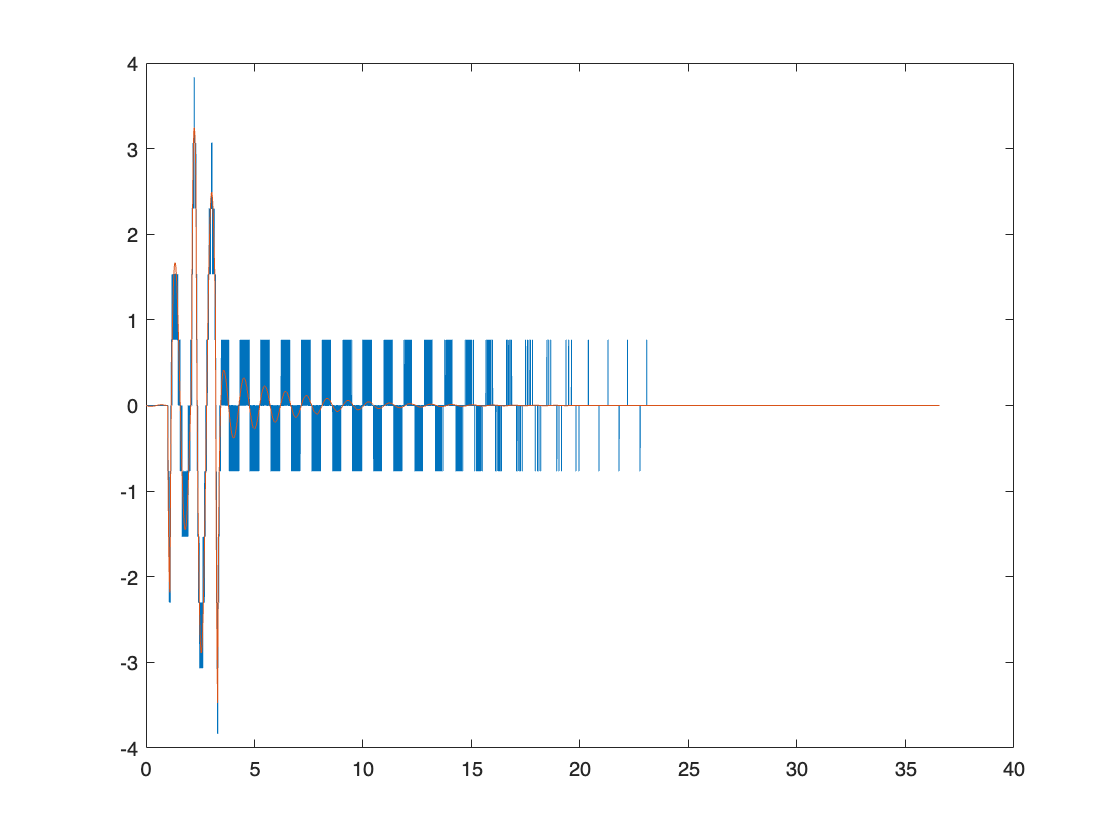

figure,plot(Time_vec,ymeas(4,:),Time_vec,ysim(4,:))

## Validation

Here we perform the validation of the identified parameters by looking at the behaviour of the non linear model against a different sineswept.

Validation with respect to the impulse response

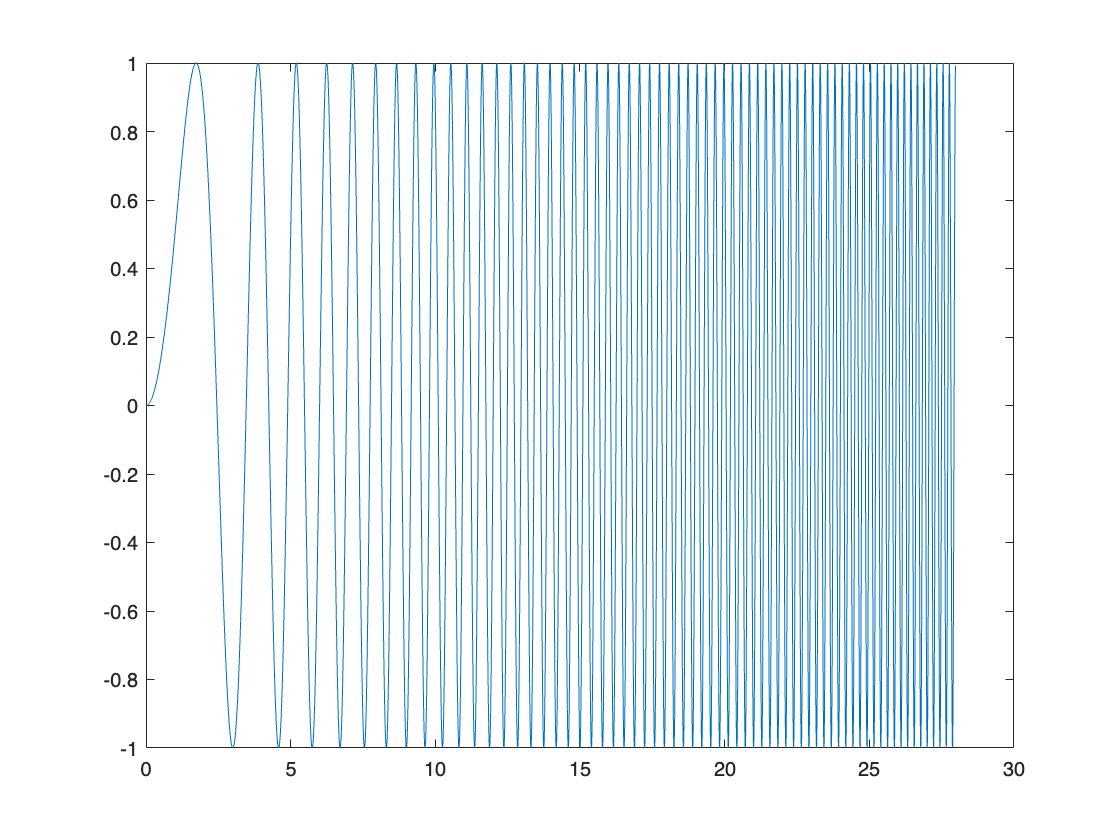

val_exp = 42;

% want row vectors !!!
uin = cell2mat(struct2cell(load('voltage_esp'+ string(val_exp)+'.mat'))); % input voltages signal collected from measurement % place negative sign
Time_vec = cell2mat(struct2cell(load('t_esp'+ string(val_exp)+'.mat'))); % time vector of the measure signals
N = length(Time_vec); % number of samples of the measurement

theta = cell2mat(struct2cell(load('theta_esp'+ string(val_exp)+'.mat')));
alpha = cell2mat(struct2cell(load('alpha_esp'+ string(val_exp)+'.mat')));
theta_dot = cell2mat(struct2cell(load('theta_d_esp'+ string(val_exp)+'.mat')));
alpha_dot = cell2mat(struct2cell(load('alpha_d_esp'+ string(val_exp)+'.mat')));

ymeas = [theta;alpha;theta_dot;alpha_dot];
z0 = [ymeas(1,1); ymeas(2,1); 0; 0]; % initial conditions given the modeling conventions

% check if voltage was measured before or after -1 gain
if uin(1,750) > 0 && theta(1,750) <= 0 || uin(1,750) < 0 && theta(1,750) >= 0
    uin = - cell2mat(struct2cell(load('voltage_esp'+ string(val_exp)+'.mat'))); % consider negative voltages
end

% simulation of the non linear system
[~,ysim] = Rot_pend_sim_err(xstar,z0,uin,ymeas,th,Ts,Q,scaling);
figure,plot(Time_vec,uin);

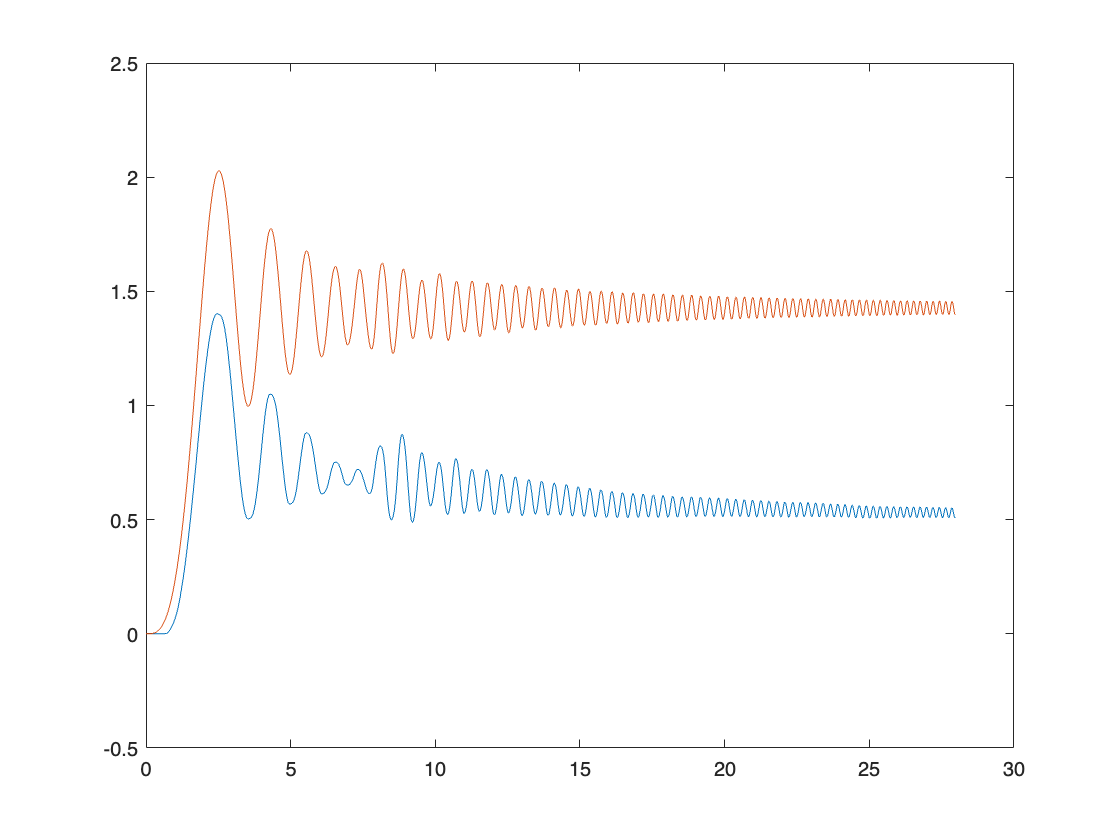

figure,plot(Time_vec,ymeas(1,:),Time_vec,ysim(1,:))

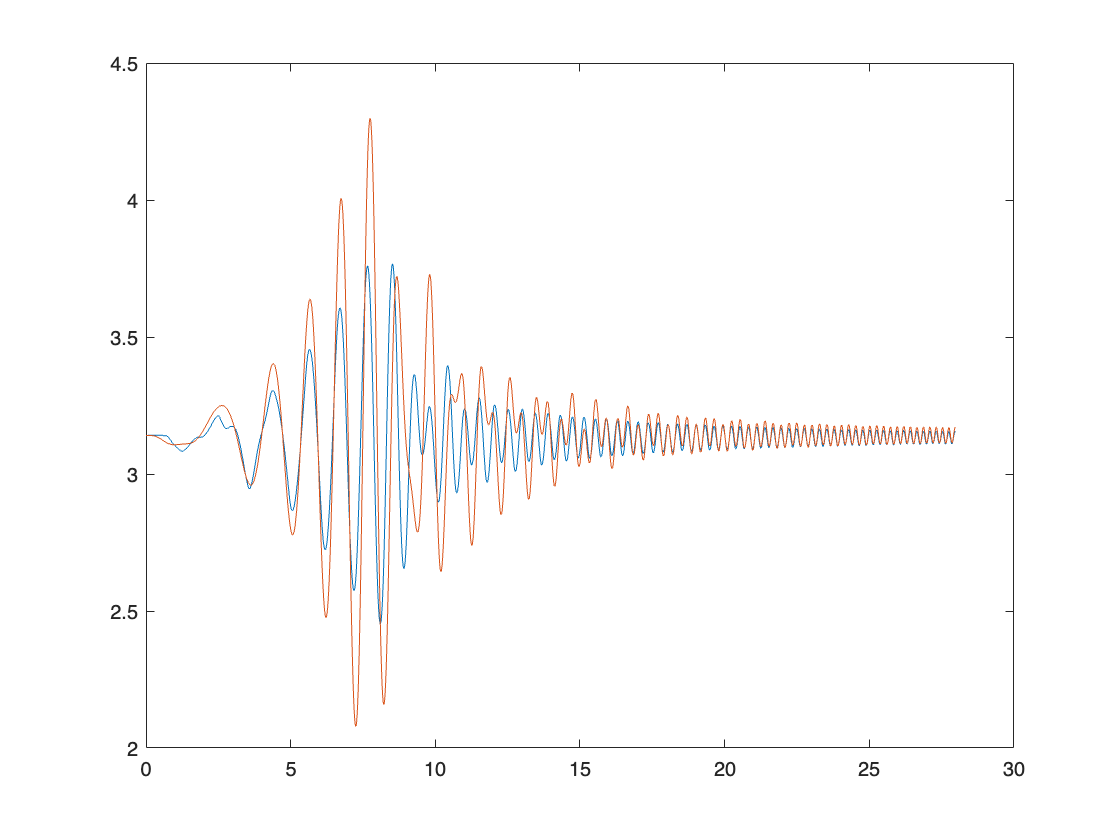

figure,plot(Time_vec,ymeas(2,:),Time_vec,ysim(2,:))

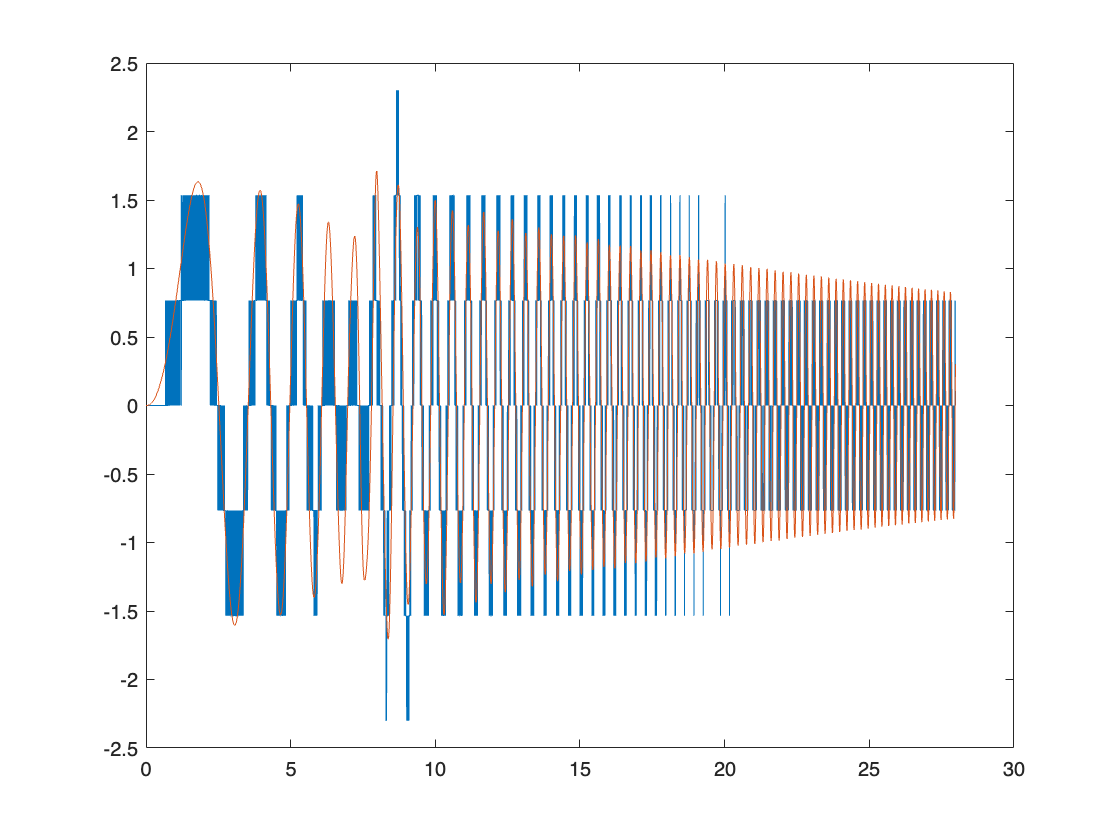


figure,plot(Time_vec,ymeas(3,:),Time_vec,ysim(3,:))

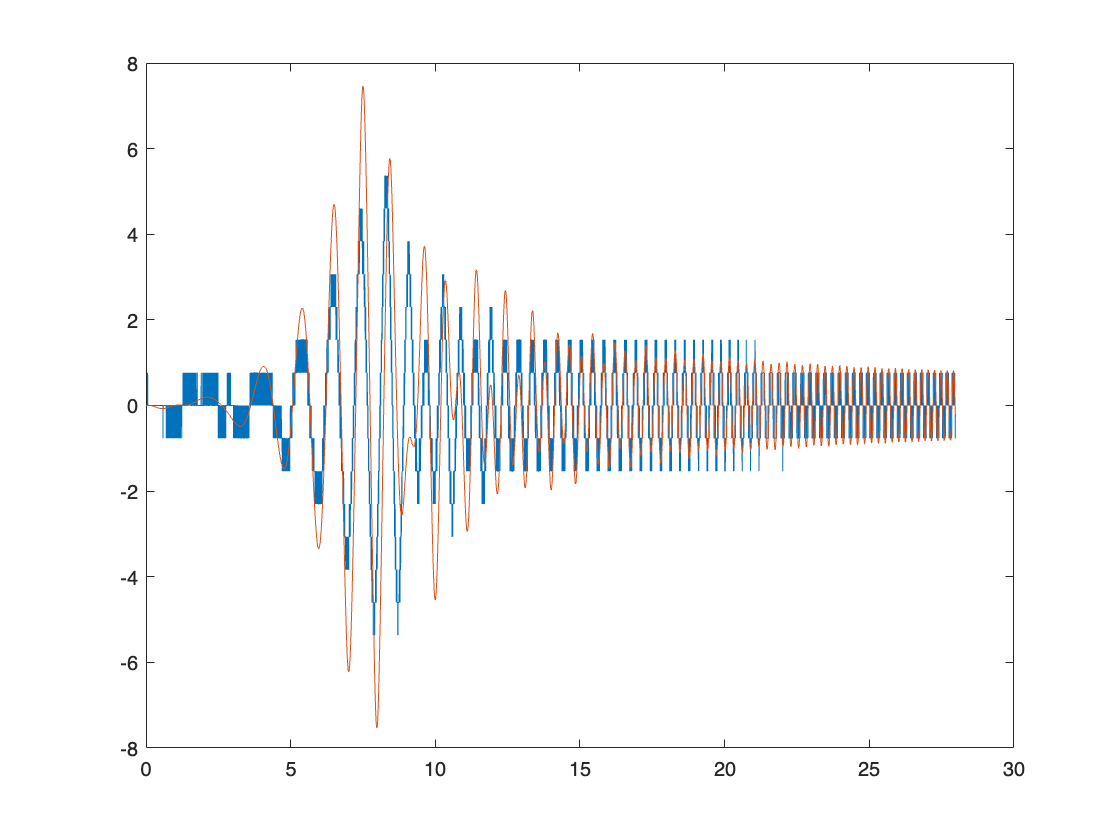

figure,plot(Time_vec,ymeas(4,:),Time_vec,ysim(4,:))